Sam Kramer 

Dr. Alfred Wicks

ME 5714: Digital Signal Processing

## Assignment 9b -- Engine Data

%{
    This will be a script that will be used to complete Assignment 9a 
    for ME 5714 -- Digital Signal Processing.

    Sam Kramer
    April 3rd, 2023
%}

% --Setup
clear; clc; close all; format compact;

### Problem Statement

Following the assignment 9, in this assignment we’ll estimate the transfer function between the pressure transducer and the microphone data.

- Select 10 independent vectors of the input, pressure sensor make the vector length 8192 samples. Create the corresponding vectors from the microphone data

- Create an ensemble of 10 resampled vectors for the the pressure transducer and the mic. You can use the ensemble of vectors you used in 9a. I found that there were about 825 samples per rotation, so you might want to resample using 720 samples per rev (each ½ degree) 

- Estimate the frequency response function and coherence using the resampled data.

- Average the vectors in the time domain and form the FRF from the averaged vectors. 

## Part 1: Creating 10 Independent vectors of the data

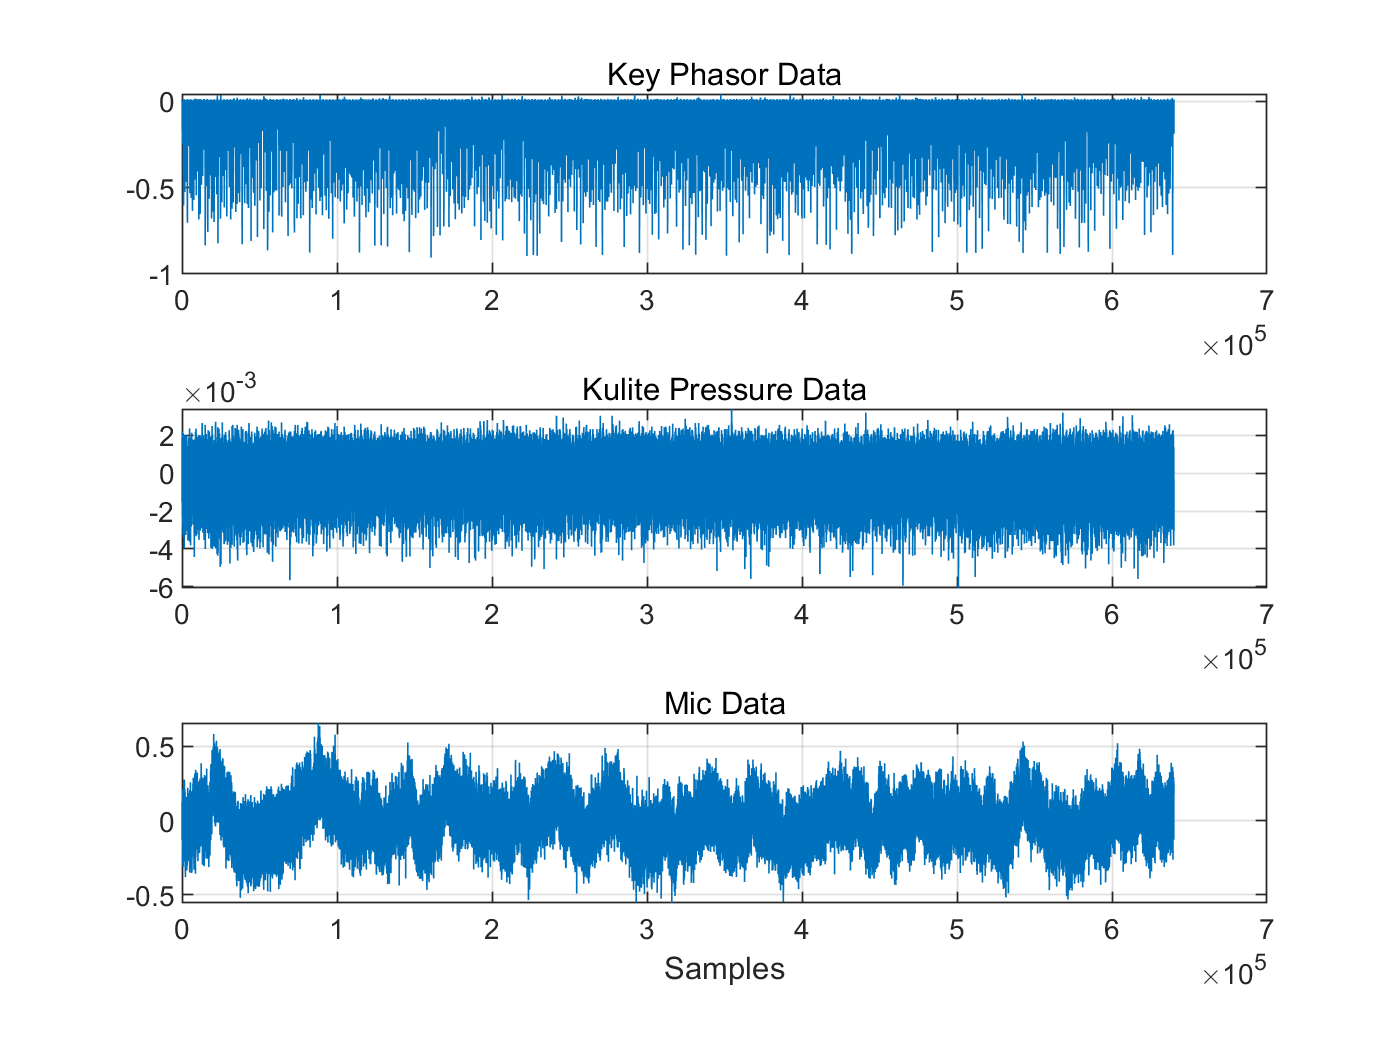

% --Load in data
    data = load('turbine data-1.mat');
    key_phasor = data.keyphasor;
    kulite_pressure = data.kulitepressure;
    mic_data = data.mic;
    
% --Zero Mean Data
    key_phasor = key_phasor - mean(key_phasor);
    kulite_pressure = kulite_pressure - mean(kulite_pressure);
    mic_data = mic_data - mean(mic_data);
    
% --Plot Data
    figure(1)
    subplot(3,1,1)
    plot(key_phasor)
        hold on
        grid on
        subtitle('Key Phasor Data')
    
    subplot(3,1,2)
    plot(kulite_pressure)
        grid on
        subtitle('Kulite Pressure Data')
    
    subplot(3,1,3)
    plot(mic_data)

        grid on
        subtitle('Mic Data')
        xlabel('Samples')
        
% --Putting pressure into data vectors
    vector_numbers = 10;
    kulite_ensemble = [];
    data_points = 8192;         % Target Number of data points
    sample_freq = 128000;       % Sample Frequency (samples/sec)
    
    for N = 1:vector_numbers
        
        kulite_ensemble = [kulite_ensemble, kulite_pressure(N*data_points:(N+1)*data_points - 1, 1)];
        
    end
    
% --Putting Mic data into 10 data vectors
    vector_numbers = 10;
    mic_ensemble = [];
    data_points = 8192;         % Target Number of data points
    
    for N = 1:vector_numbers

        mic_ensemble = [mic_ensemble, mic_data(N*data_points:(N+1)*data_points - 1, 1)];
        
    end

## Part 2: Resampling Data

% --Resample data using my own for loop function
    resampled_kulite = resample_matrix(kulite_ensemble, 155*720, 128000);
    resampled_mic = resample_matrix(mic_ensemble, 155*720, 128000);

## Part 3: Estimating FRF and Coherence of Resampled Data

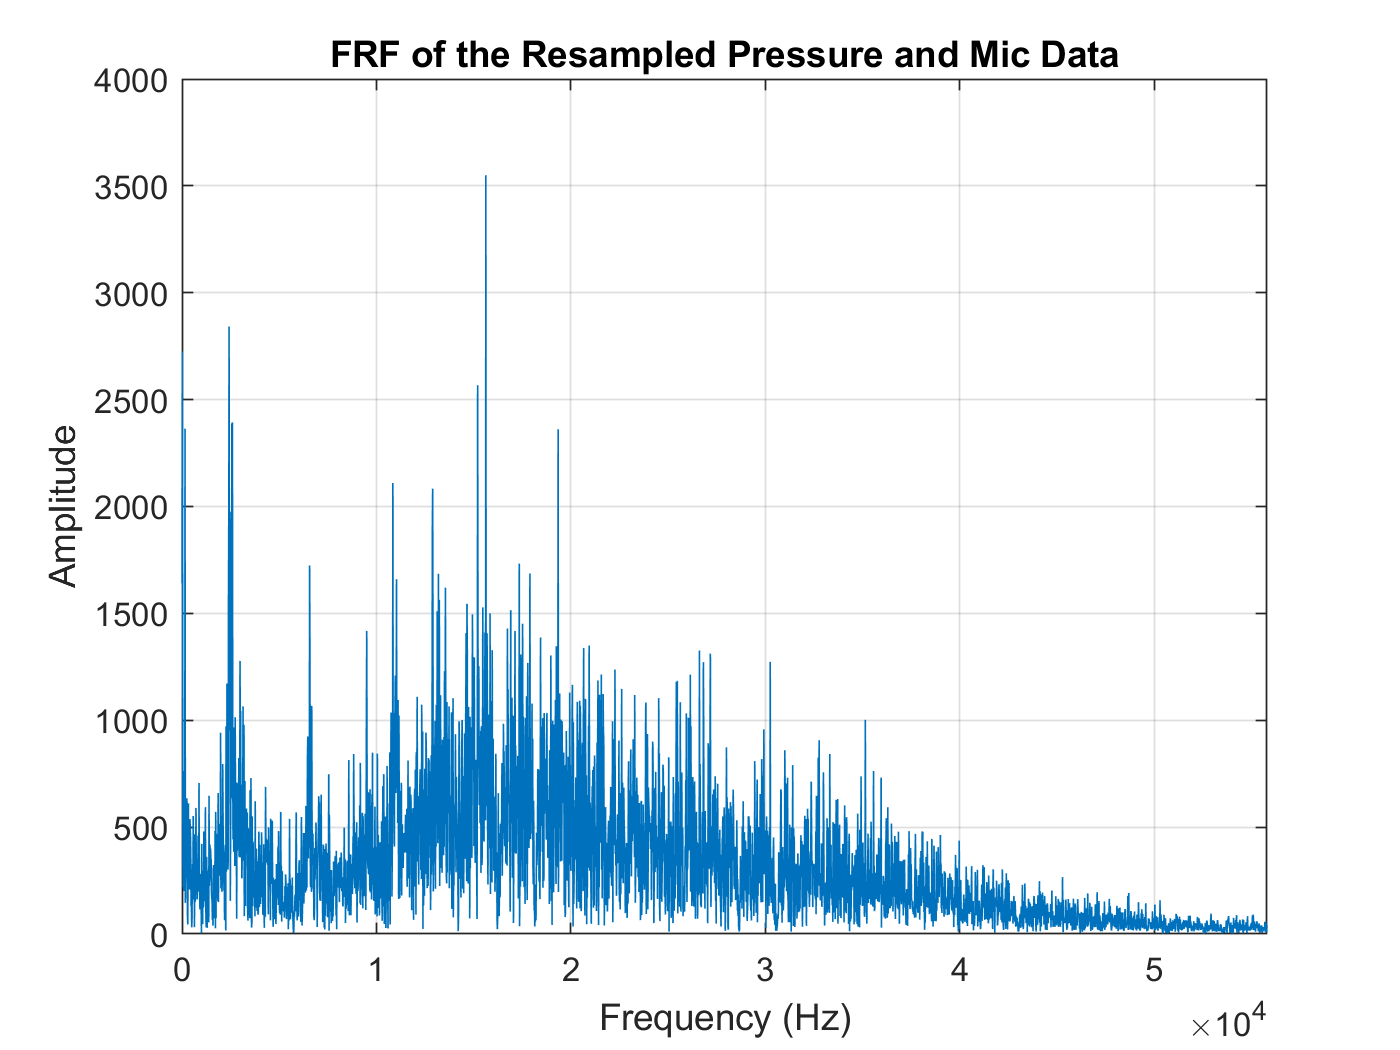

% --Finding the FRF 
    Gxx = autospec(resampled_kulite);
    Gxy = crossspec(resampled_kulite, resampled_mic);
    FRF = abs(Gxy) ./ Gxx;
    
% --Changing frequency
    data_points = length(resampled_mic);
    sample_freq = 155*720;
    T = data_points/sample_freq;
    freq = (1/T)*(0:(data_points - 1));
    
% --Plotting FRF
    figure(2)
    plot(freq, FRF)
        hold on
        xlim([0 max(freq)/2])
        xlabel('Frequency (Hz)')
        ylabel('Amplitude')
        grid on
        title('FRF of the Resampled Pressure and Mic Data')

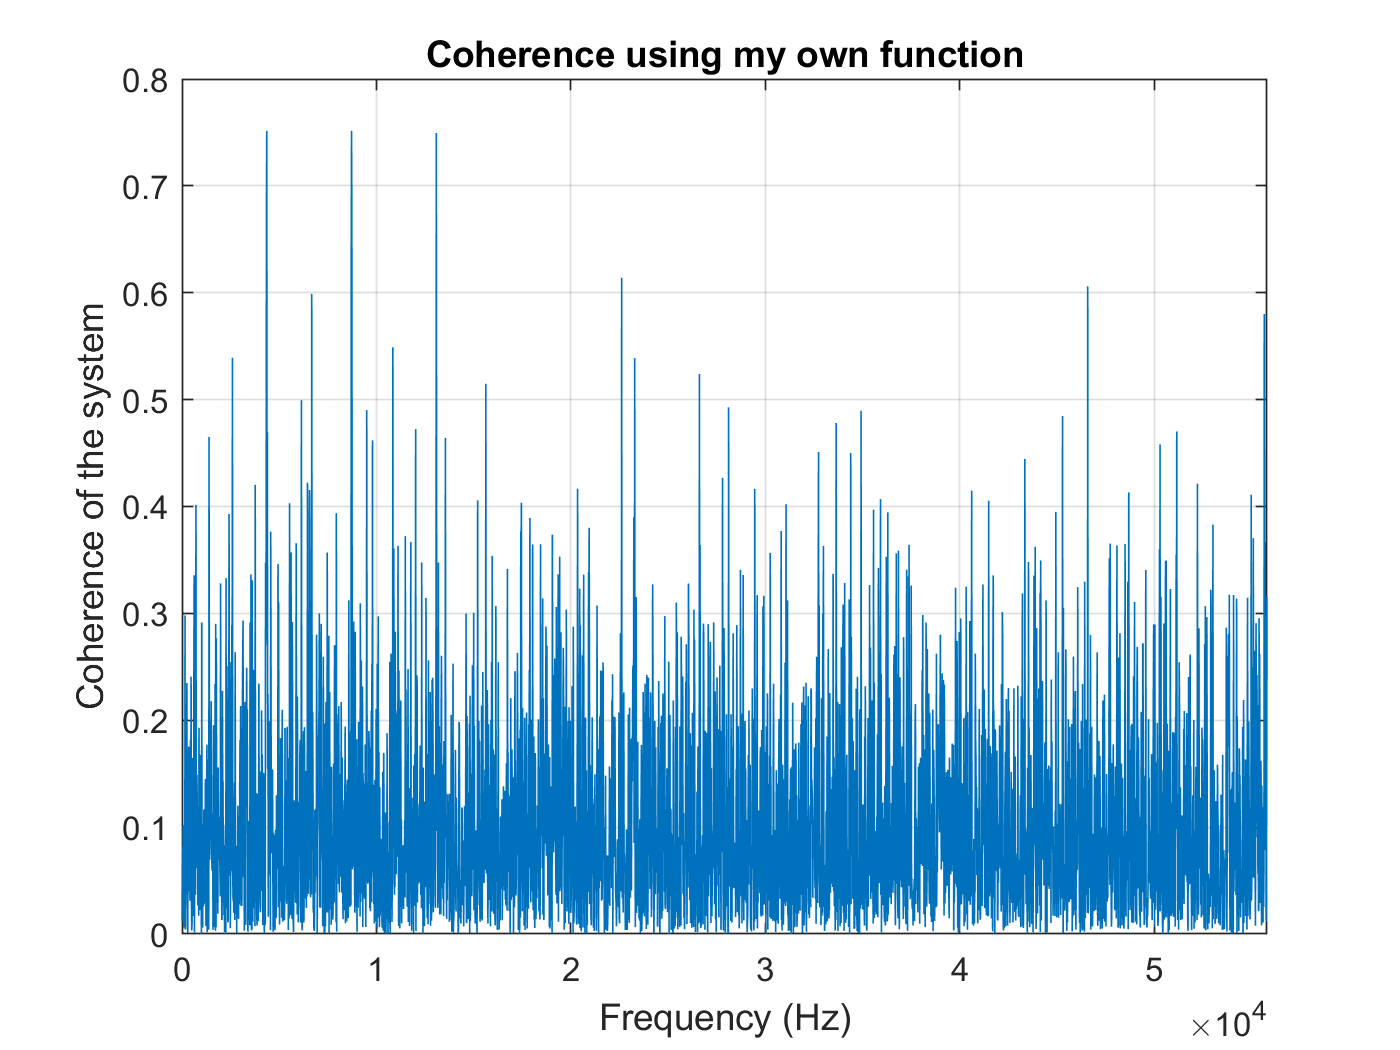

        
% --Estimating Coherence
    gamma_squared = coherence(resampled_kulite, resampled_mic);
    
% --Plotting Coherence function
    figure(3)
    plot(freq,gamma_squared)
        title('Coherence using my own function')
        xlabel('Frequency (Hz)')
        xlim([0 max(freq)/2])
        grid on
        hold on 
        ylabel('Coherence of the system')

        
% --Printing out the average of the coherence funciton 
    fprintf('The coherence of the signals is an average of %0.3f. \n', mean(gamma_squared))

The coherence of the signals is an average of 0.104. 


## Part 4: Average the vectors in the time domain and form the FRF

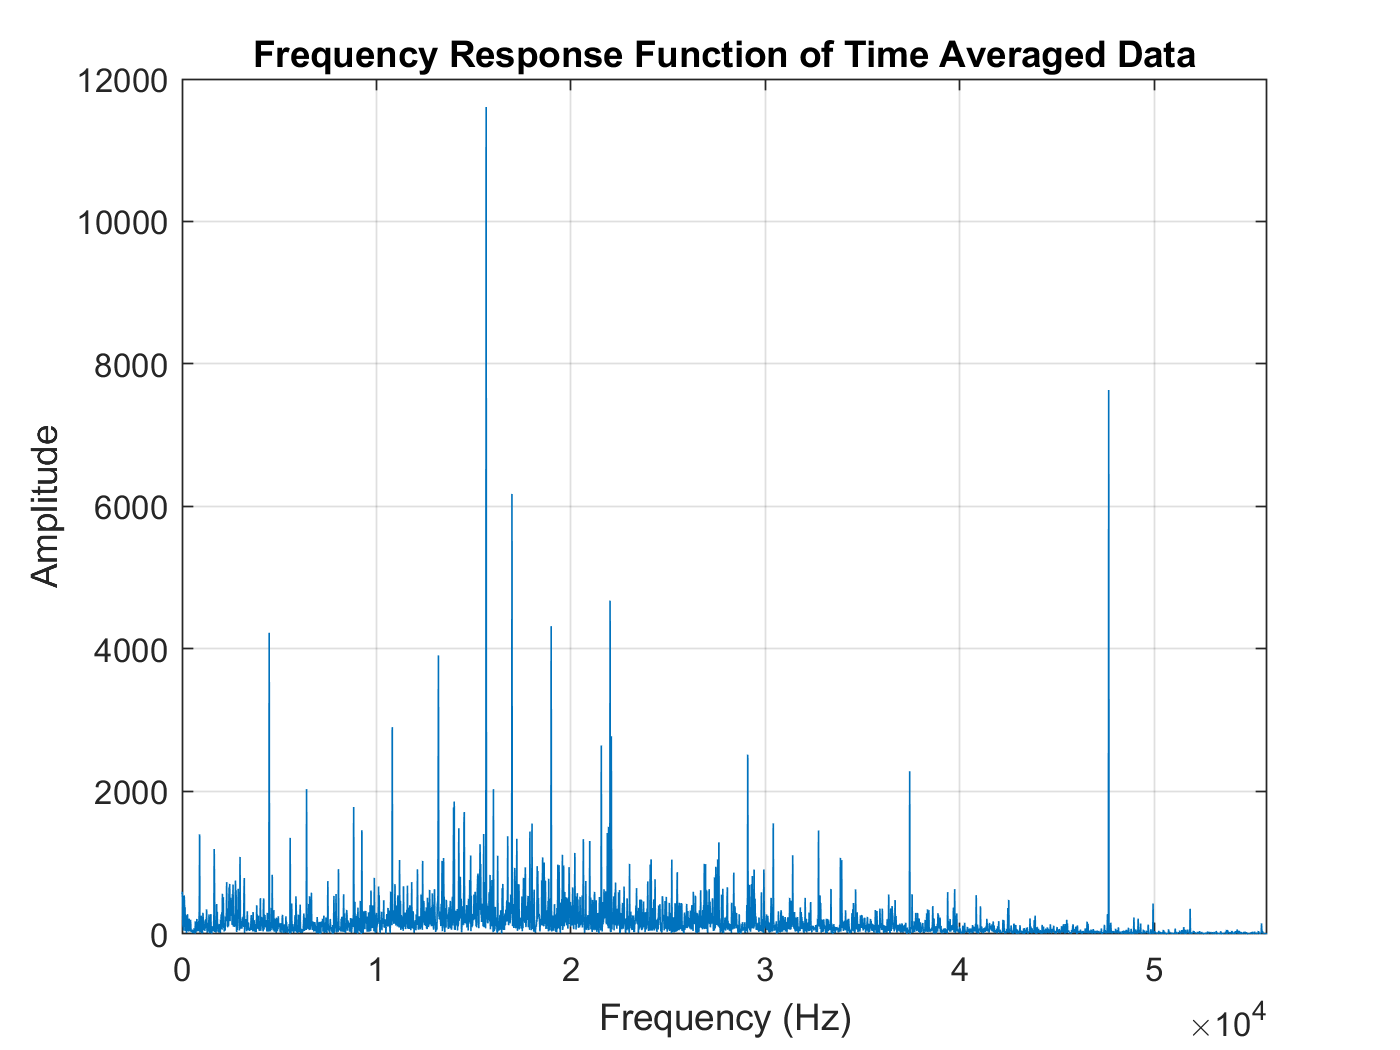

% --Finding the mean of all the vectors in the time domain
    kulite_single = mean(resampled_kulite,2);
    mic_single = mean(resampled_mic,2);
    
% --Finding auto and cross spectrums
    Gxx = autospec(kulite_single);
    Gxy = crossspec(kulite_single,mic_single);
    
% --Estimating the FRF of the averaged vectors
    FRF_averaged = abs(Gxy) ./ Gxx;
    
% --Plotting
    figure
    plot(freq,FRF_averaged);
        xlim([0 max(freq)/2])
        grid on
        xlabel('Frequency (Hz)')
        ylabel('Amplitude')
        title('Frequency Response Function of Time Averaged Data')

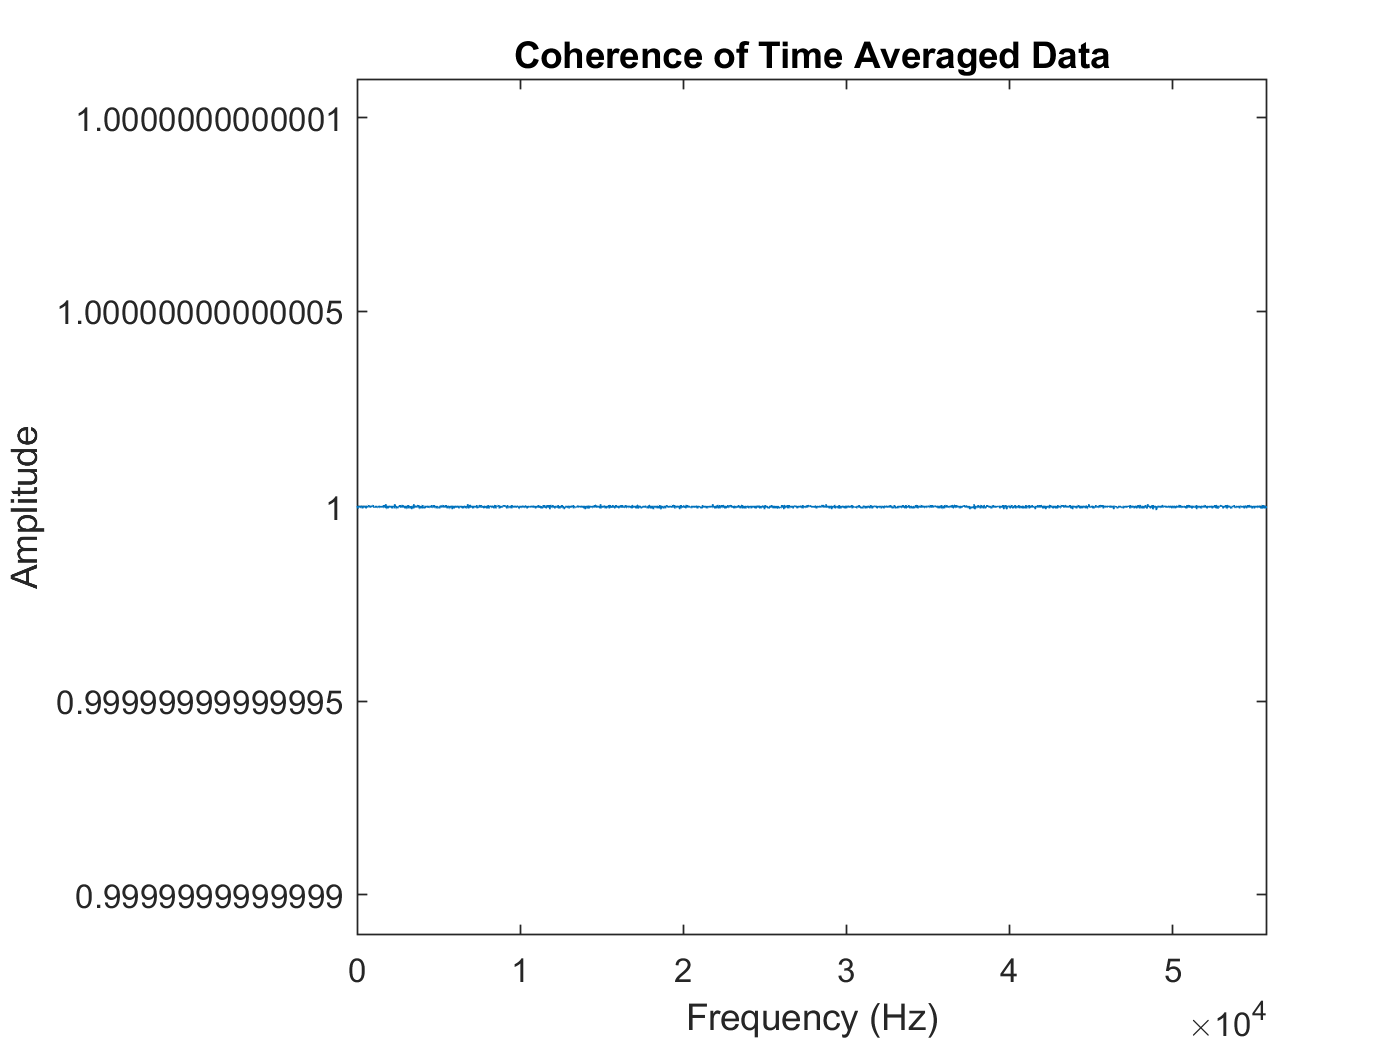

        
% --Finding coherence
    gamma_squared_avg = coherence(kulite_single, mic_single);
    
% --Plotting Coherence
    figure
    plot(freq, gamma_squared_avg)
        xlabel('Frequency (Hz)')
        ylabel('Amplitude')
        xlim([0 max(freq)/2])
        title('Coherence of Time Averaged Data')

## Functions

function resampled_data = resample_matrix(data, A, B)
    %{
        This function will resampled the data within a matrix of N columns
        wide.
    %}

    % --Setup
        resampled_data = [];
    
    % --For loop
        for i = 1:width(data)
            
            re_data = resample(data(:,i),A,B);
            resampled_data = [resampled_data, re_data];
            
        end
end

function auto_spect = autospec(data)
    %{
        Finds autospectrum of data, data can be both a single vector and a
        matrix of multiple columns.
    %}

    % --Setup
        auto_spect = zeros(length(data),1);
    
    % --Compute autospectrum of data
        for i = 1:width(data)
        
            % --Take FFT of Column data
                fftdata = fft(data(:,i));
            
            % --Find autospectrum and add it to previous value
                auto = fftdata .* conj(fftdata);
                auto = auto * 2 / (length(data)*width(data));
                auto_spect = auto_spect + auto;
        
        end
        
    % --Normalize
        auto_spect = auto_spect/ (width(data));
        
end

function cross_spect = crossspec(data1,data2)
    %{
        Performs the cross spectrum of data1 and data2 using (x*)(y) where
        x* is the complex conjugate of the fft of data1.
    %}
    
    % --Setup
        cross_spect = zeros(length(data1),1);
    
    % --Compute autospectrum of data
        for i = 1:width(data1)
        
            % --Take FFT of Column data
                fftdata1 = fft(data1(:,i));
                fftdata2 = fft(data2(:,i));
            
            % --Find cross-spectrum and add it to previous value by (X*)(Y)
                cross = fftdata2 .* conj(fftdata1);
                cross = 2 .* (cross) / length(data1);
                cross_spect = cross_spect + cross;
        
        end
        
    % --Normalize
        cross_spect = cross_spect / (width(data1));

end

function coherence_function = coherence(input, output)
    %{
        Finds the coherence of the data, can be multiple input or single
        output. Input size must be same as output size.
    %}

        % --Finding Gxx and etc..
            Gxx = autospec(input);
            Gyy = autospec(output);
            Gxy = crossspec(input,output);
            Gyx = crossspec(output,input);
            
        % --Compute Gamma square coherence
            gamma_squared = abs((Gxy.*Gyx) ./ (Gxx.*Gyy));
            gamma_squared = gamma_squared / (width(input)^2);
            
        % --Save gamma_squared
            coherence_function = (gamma_squared);
                

end